# Using simulink to visualise position system behaviour

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours. However, the real world is full of more complex components and connections. In such cases writing code can be messy or difficult and it is often easier to capture the scenario using tools such as simulink.

This livescript is a brief introduction to the use of simulink to model and simulate a simple position system. More importantly, it shows how integration with MATLAB code can make running the simulink file very efficient to allow systematic investigations for a range of parameter values and specifically in this case, the impact of the inclusion of non-linear components which are harder to handle in simple MATLAB code. This livescript file makes use of the following simulink files:

- Position_system_control101.slx 

- Position_system_saturation_control101.slx 

- Position_system_backlash_control101.slx 

For more generic and comprehensive help on and introduction to Simulink, use the Mathworks onramp website.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

*****************************


File written by J.A.Rossiter, University of Sheffield                         

## Preamble

Many simulink files have a large number of parameters which are most conveniently defined with a supporting MATLAB script and thus one might as well run the simulink file directly from the same script. This resource collects the core parameter values from the workspace and a step input component. The outputs are sent to a scope and an output block (labelled '1'). it is easiest to define the required parameter values in a short MATLAB script and also use this script to run the file; options can make the scope open automatically but, one can also use the script to generate a neater plot using the data sent to the workspace.

For more generic and comprehensive help on and introduction to Simulink, use the Mathworks onramp website.

## 1. Simple position system models

The angular displacement of the DC motor is translated into a linear movement by means of a mechanical transmission chain. The input voltage* u* applied to the armature circuit of the motor is supplied by an analogue controller based on the tracking error *e* between the prescribed reference *z* and the position *y* of the tool. The measured position *ym* of the tool is obtained by means of a potentiometer based transducer. A schematic of this system is given below in Figure 1 and the equivalent block diagram is given in Figure 2. 

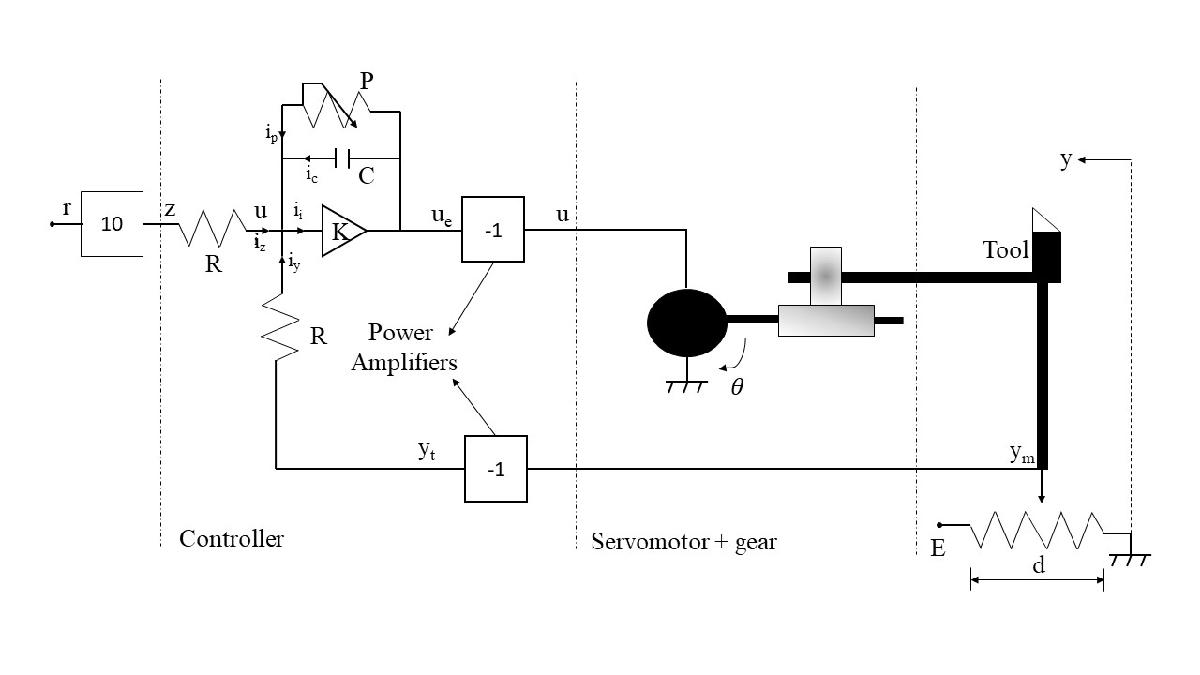

**Figure 1.1**. Schematic of positioning system

The corresponding transfer function models are not derived here, but rather just symmarised as this still shows the dependence on the different system components.

$G_c \left(s\right)=\frac{\frac{1}{\textrm{RC}}}{s+\frac{1}{\textrm{PC}}}$;       $G_m \left(s\right)=\frac{k_m k_s }{s}$;     $G_t =\frac{E}{d}$;  $\overset{\ldotp }{\theta} =k_s u;$    ${y=k}_m \theta$.

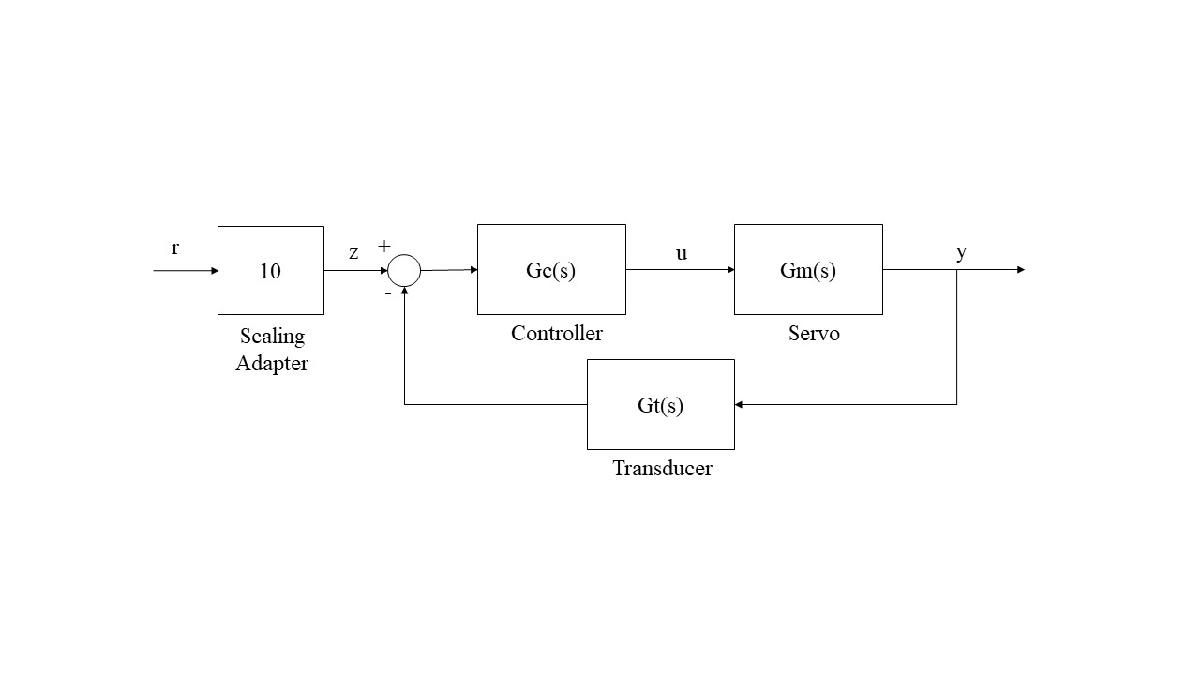

**Figure 1.2**. Block diagram representation of the positioning system

## 2. Simulink files and simulation

A simulink file captures  the block diagram of Figure 1.2 and is shown in Figure 2.1 below. The output is sent to both the scope and the workspace and the input is a simple unit step.

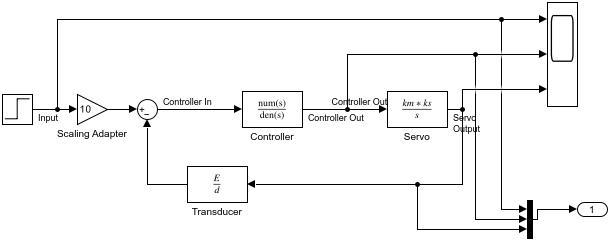

**Figure 2.1**: Screen capture of*** Position_System_control101.slx.*** 

### 2.1 Running the simulink file

The data required can be defined in a simple script and the 'sim' command used to run the file. Given the output component choice, a default naming of *tout* and *yout* is used for the data. Typical code to run the file and display the results is given here.

disp('*****************************')

Section 2 illustrations below


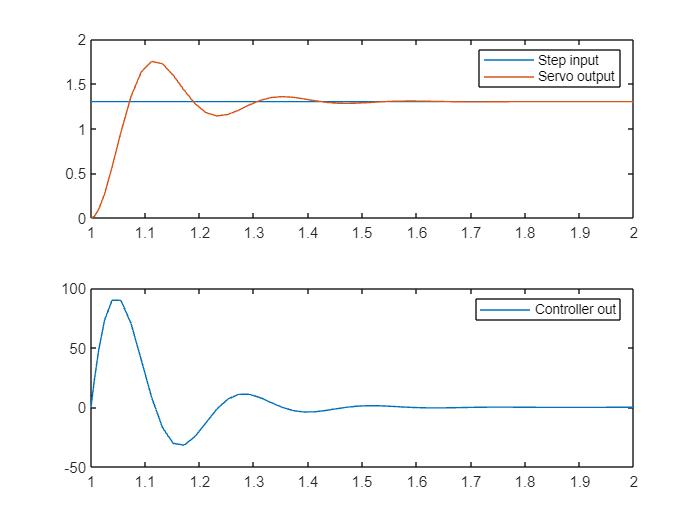

disp('Section 2 illustrations below')

% define default parameter values
R=10E3;
P=170E3;
C=0.33E-6;
ks=52.5;
km=5E-3;
E=10;
d=1;
stoptime=2;

% to open simulink file and view the scopes
% open Position_System_control101.slx  

% Simulation - results will appear in the scopes
sim("Position_System_control101.slx");
subplot(211);plot(tout,yout(:,[1 3]))
legend('Step input','Servo output')
subplot(212);plot(tout,yout(:,2))

legend('Controller out')

%print(['-sPosition_System_control101'],'-djpeg',['Position_System_control101.jpg'])

### 2.2 Adding saturation

Real systems have limits on the available power/voltage/current and so forth. The next file gives a very small extension whereby a saturation block is added to the controller signal. Otherwise running this file and viewing results is the same procedure as earlier. The figures/scope clearly show the difference between the demanded signal 'u' and the delivered 'u' which is saturated at 10.

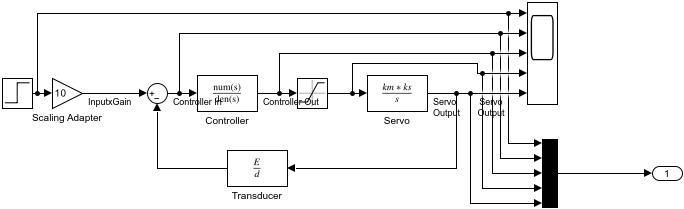

**Figure 2.2**: Screen capture of*** Position_System_saturation_control101.slx.*** 

disp('*****************************')

*****************************


disp('Section 2.2 illustrations below')

Section 2.2 illustrations below


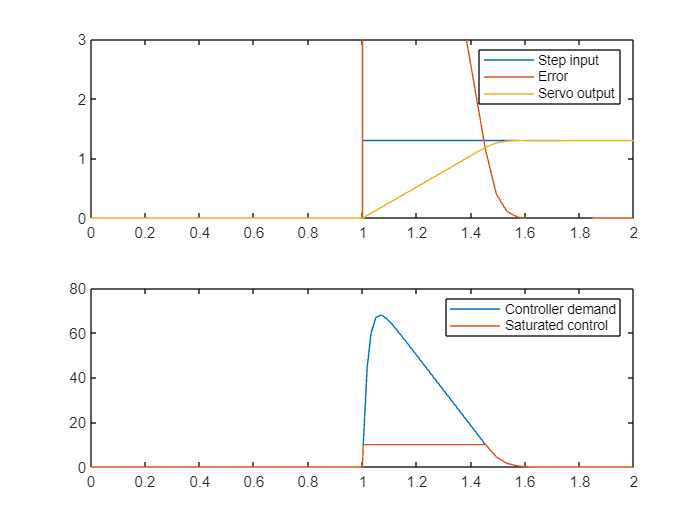


% define default parameter values
R=10E3;
P=60E3;
C=0.33E-6;
ks=52.5;
km=5E-3;
E=10;
d=1;


% to open simulink file and view the scopes
% open Position_System_saturation_control101.slx  

% Simulation - results will appear in the scopes
sim("Position_System_saturation_control101.slx");

subplot(211);plot(tout,yout(:,[1 2 5]));
ylim([0,3])
legend('Step input','Error','Servo output')
subplot(212);plot(tout,yout(:,[3 4]))
legend('Controller demand','Saturated control')


%print(['-sPosition_System_saturation_control101'],'-djpeg',['Position_System_saturation_control101.jpg'])


### 2.3 Adding backlash

Real gearing systems are often subject ot backlash and thus non-linear behaviours during changes in direction. The next example illustrates the impact of such a component. it would be straightforward to augment the input singal from a step to investigate this behaviour more generally.

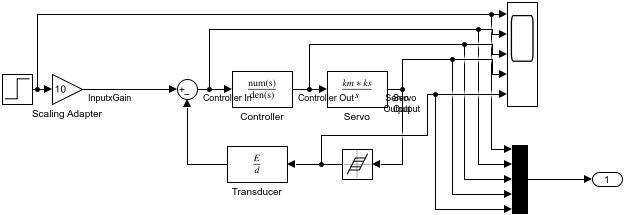

**Figure 2.2**: Screen capture of*** Position_System_backlash_control101.slx.*** 

disp('*****************************')
disp('Section 2.3 illustrations below')

*****************************


Section 2.3 illustrations below


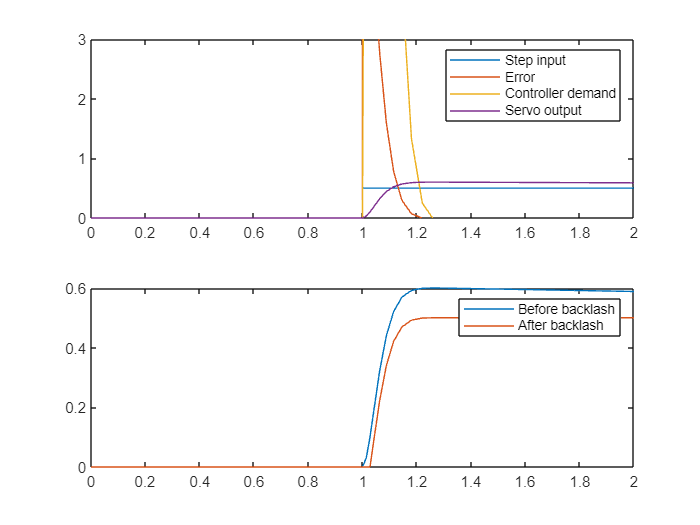

% define default parameter values
R=10E3;
P=60E3;
C=0.33E-6;
ks=52.5;
km=5E-3;
E=10;
d=1;


% to open simulink file and view the scopes
% open Position_System_backlash_control101.slx  

% Simulation - results will appear in the scopes
sim("Position_System_backlash_control101.slx");

subplot(211);plot(tout,yout(:,[1 2 3 4]));
ylim([0,3])
legend('Step input','Error','Controller demand','Servo output')
subplot(212);plot(tout,yout(:,[4 5]))
legend('Before backlash','After backlash')


%print(['-sPosition_System_backlash_control101'],'-djpeg',['Position_System_backlash_control101.jpg'])
